# Classify Static Image Using Deep Learning on Raspberry Pi

This example shows you how to generate and deploy code for an image classification algorithm using MATLAB® Support Package for Raspberry Pi®  Hardware. The algorithm uses the ResNet-50 neural network to identify the image that is passed as an input using the command line of Raspberry Pi. 

When you generate code for prediction the Raspberry Pi support package builds the executable on the hardware. Using ResNet-50, the executable classifies images into 1000 object categories, such as keyboard, coffee mug, pencil, and many animals. The executable predicts the object and outputs a label for it along with the associated probability of object category.

Note: You cannot generate and deploy deep learning code on Raspberry Pi hardware using macOS. 

## Required Hardware

- Raspberry Pi hardware (Model 4 recommended)

- USB cable

- Ethernet cable

- A monitor connected to the Raspberry Pi hardware and a HDMI cable (optional)

## Prerequisite

**Configure the Raspberry Pi using the **[**Hardware Setup**](docid:mlsupportpkg#bt7xwov-2.mw_ce00da2f-bde9-4f39-a69a-a9aaf014dbc0)** screen**. Customize the OS on your hardware and ensure that you select the option to install the OpenCV Library.

## **Step 1: Connect the Raspberry Pi Hardware**

**Tip**: Before you start this example, we recommend you to complete the [Getting Started with MATLAB Support Package for Raspberry Pi Hardware](docid:mlsupportpkg.example-raspi_gettingstarted) and [Get Inputs to a MATLAB Function from Command Line of Raspberry Pi](docid:mlsupportpkg.example-simplesum_ssh) examples.

Connect the micro end of the USB cable to the Raspberry Pi and the regular end of the USB cable to the computer. Wait until the PWR LED on the hardware starts blinking.

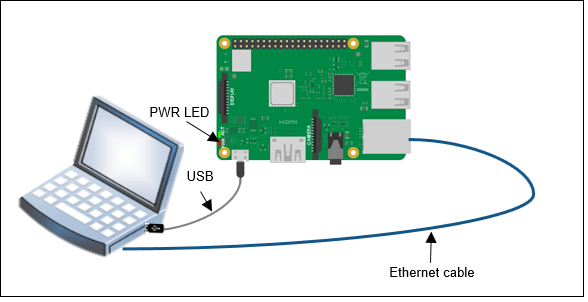

In the MATLAB® Command Window, create a connection to the Raspberry Pi hardware.

r = raspi("rpi4b040308eth");

## Step 2: Open the Object Classification Algorithm

In this example, the `raspi_fileRead_resnet` function loads the ResNet-50 deep learning neural network to classify the input image. The function resizes the image using OpenCV to fit the size expected by the network. It then classifies the image into object categories and outputs a label for object predictions along with the probabilities for each of the object categories. 

For more information on the function, enter this command in the MATLAB Command Window.

type raspi_fileRead_resnet

You can modify the function by using the `edit` command.

## Step 3: Generate C++ Code for Image Classification on Raspberry Pi

Create a hardware configuration object by using the [targetHardware](docid:mlsupportpkg.mw_0826d141-e828-41a5-b465-cdf6268cb39a) function in the MATLAB Command Window.

For Raspberry Pi with 32-bit OS, use: 

For Raspberry Pi with 64-bit OS, use: 

board = targetHardware('Raspberry Pi (64bit)')

Set the `DeviceAddress.`

board.DeviceAddress='rpi4b040308eth';
board.Username = 'pi';
board.Password = 'raspberry';
board.BuildDir = '/home/pi';

Verify the `DeviceAddress`, `Username`, and `Password` properties listed in the output. If required, change the value of the properties by using the dot notation syntax. For example, to change the device address to `172.18.186.123`, enter, 

Set the `CoderConfig.GenCodeOnly` property of the board object to `true`. This enables the support package to generate and run the image classification algorithm code only on the host computer.

board.CoderConfig.TargetLang = 'C++';
board.CoderConfig.GenCodeOnly = true;

Create deep learning configuration object. Specify the TargetLibrary to 'none' to generate library free code.

dlcfg = coder.DeepLearningConfig(TargetLibrary = 'none');

You can use `CodeReplacementLibraries` for improved run-time execution. To utilize "ARM CORTEX-A CMSIS CRL", please make sure you have installed the following:

- Embedded Coder and 

- "Simulink Support package for Raspberry Pi" or "Embedded Coder support package for ARM Cortex-A"

You can run the following command in the command window:

Set the `DeepLearningConfig` property of the code generation configuration object to the deep learning configuration object.

board.CoderConfig.DeepLearningConfig = dlcfg;

Deploy the function on the hardware by using the [deploy](docid:mlsupportpkg.mw_a8a63ef5-1af4-460a-8515-2432dd5670b6) function. The `deploy` function initiates code generation of the `raspi_fileRead_resnet` function. Once code generation is complete, MATLAB generates a code generation report. Use this report to debug the function for any errors and warnings in the generated code.

After successfully generating the code, update the `main.cpp` file to accept command line arguments.

deploy(board,'raspi_fileRead_resnet');

## **Step 4: Edit C++ Main File to Accept Input from Command Line of Raspberry Pi**

This section explains how to modify the `main.cpp` file to provide inputs using the command line of Raspberry Pi. A premodified `main.cpp` file is available for you to use. You can choose to use the premodified file or to update the file manually using the steps in this section.

To use the premodified `main.cpp`  and `mail.h` files, enter this command in the MATLAB Command Window.

copyfile('main.h',fullfile(pwd,'codegen','exe','raspi_fileRead_resnet'),'f')
copyfile('main.cpp',fullfile(pwd,'codegen','exe','raspi_fileRead_resnet'),'f')

To update the file manually, copy the generated `main.cpp` and `main.h` files to one level higher than the current level in the file hierarchy. Open the `main.cpp` file from the **GENERATED CODE** section of the code generation report and update the file by adding code at the points labeled in this code.

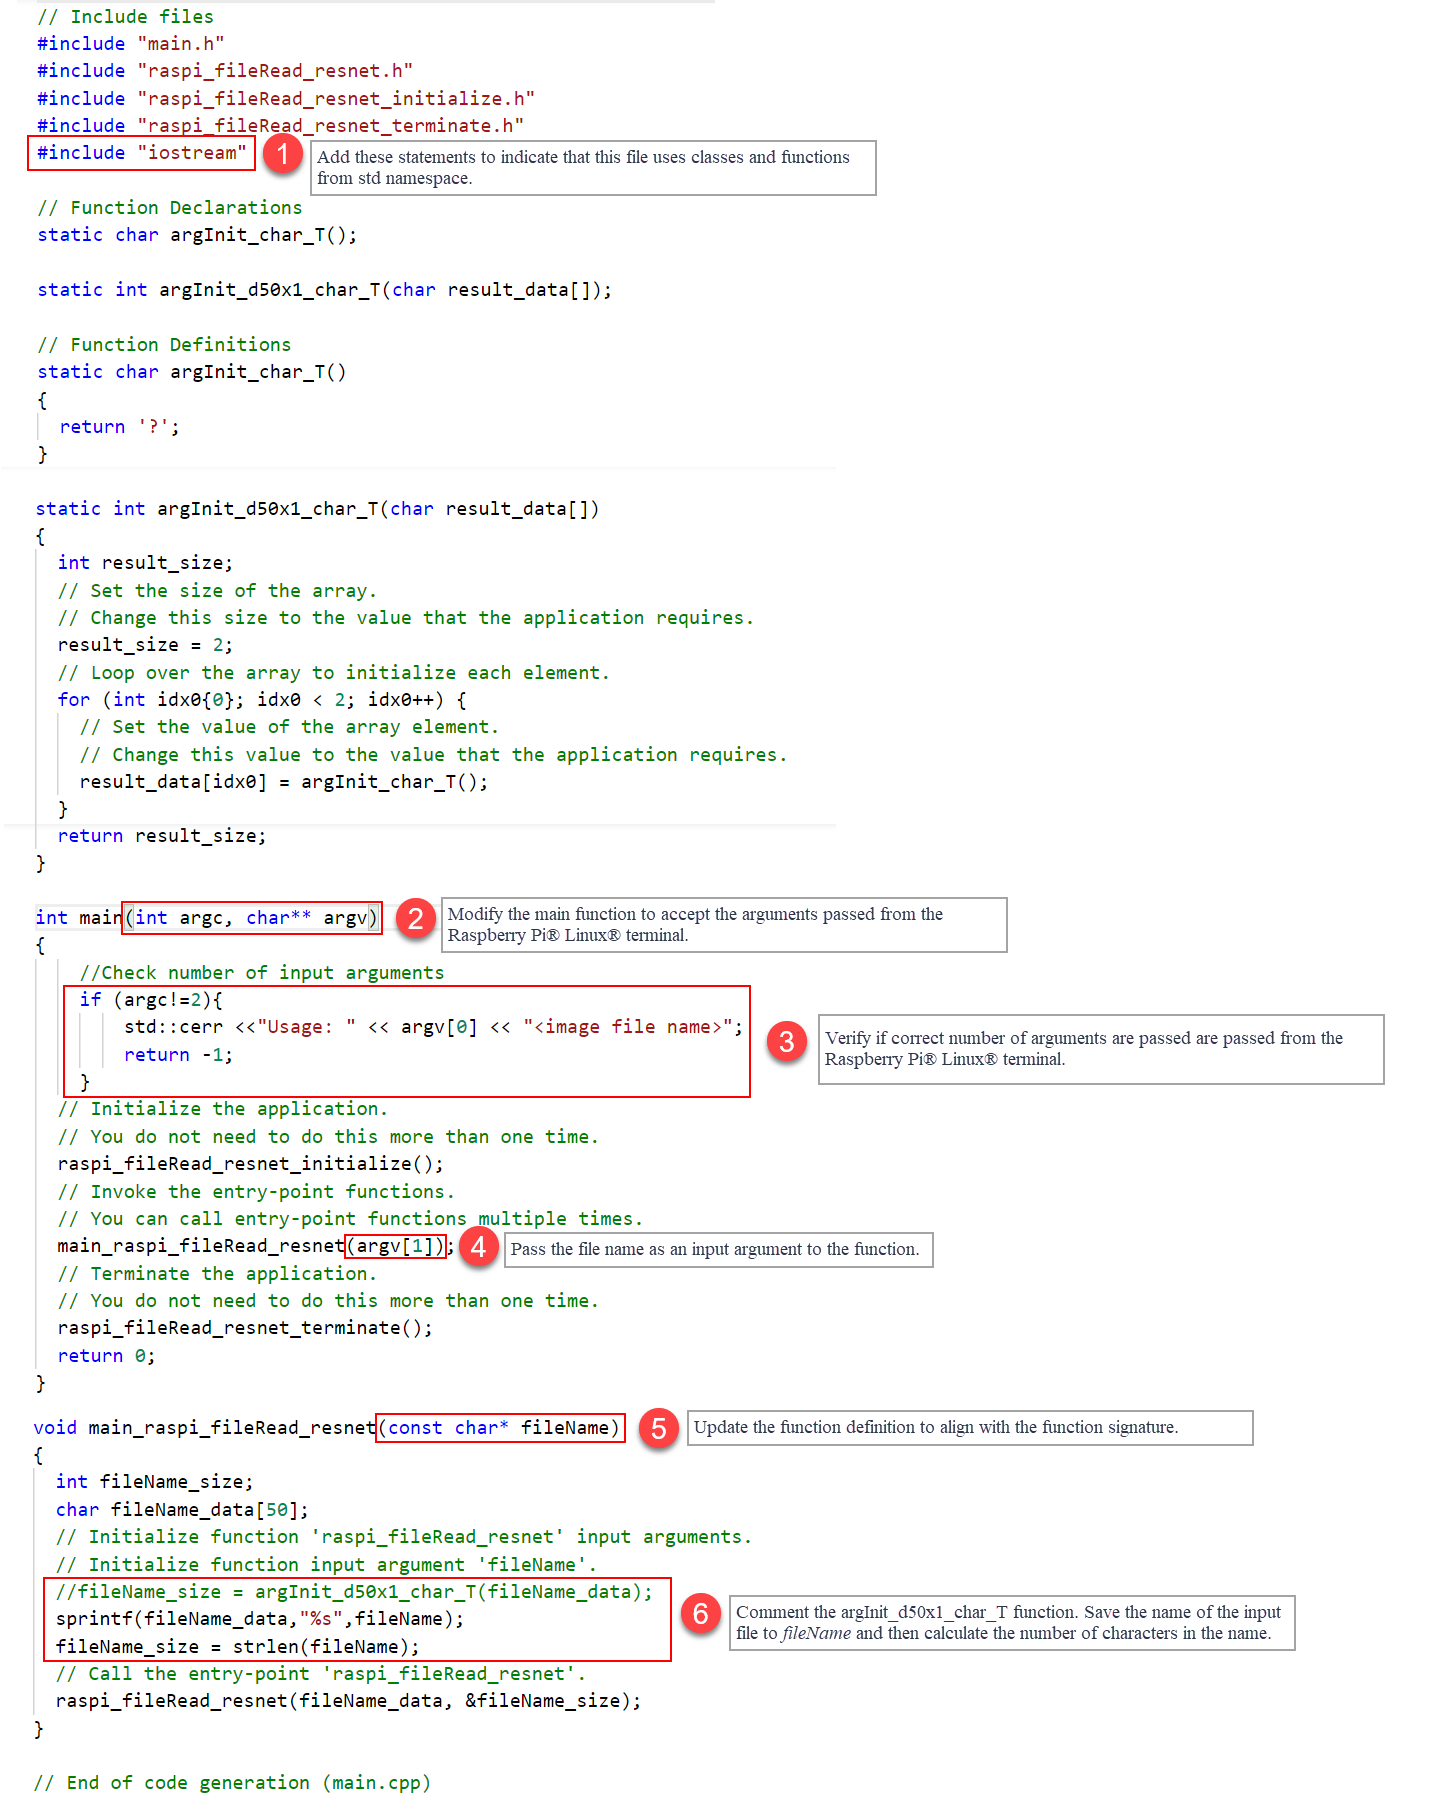

Open the `main.h` file from the **GENERATED CODE** section of the code generation report and update the file by adding code at the points labeled in this code.

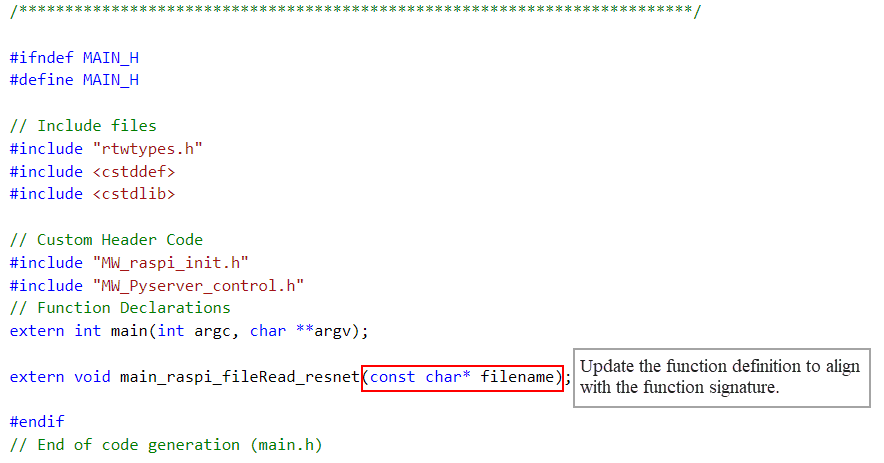

## **Step 5: Deploy the Function as a Standalone Executable on the Raspberry Pi**

To generate and deploy the code on the hardware, set the `CoderConfig.GenCodeOnly` property of the `board` object to `false` and then use the [deploy](docid:mlsupportpkg.mw_a8a63ef5-1af4-460a-8515-2432dd5670b6) function. Since the `deploy` function overwrites the` main.cpp` file that you edited in the previous section, disable the creation of the file before deployment. 

board.CoderConfig.CustomSource = {fullfile(pwd,'codegen','exe','raspi_fileRead_resnet','main.cpp')}
board.CoderConfig.CustomInclude = {fullfile(pwd,'codegen','exe','raspi_fileRead_resnet')}
board.CoderConfig.GenerateExampleMain = 'DoNotGenerate';
board.CoderConfig.GenCodeOnly = false
deploy(board,'raspi_fileRead_resnet')

The `deploy` function initiates code generation of the `raspi_fileRead_resnet` function.

After successfully generating the code, the support package loads the object classification algorithm as a standalone executable on the hardware. The location of the executable is displayed in the MATLAB Command Window. Note the location for later use.

## Step 6: Copy Image File to the Raspberry Pi

- After the code generation report has been successfully generated, click **View report** from the previous section.

- On the **MATLAB Coder Report Viewer** window, on the **Build Logs** tab, copy the location of the generated elf. 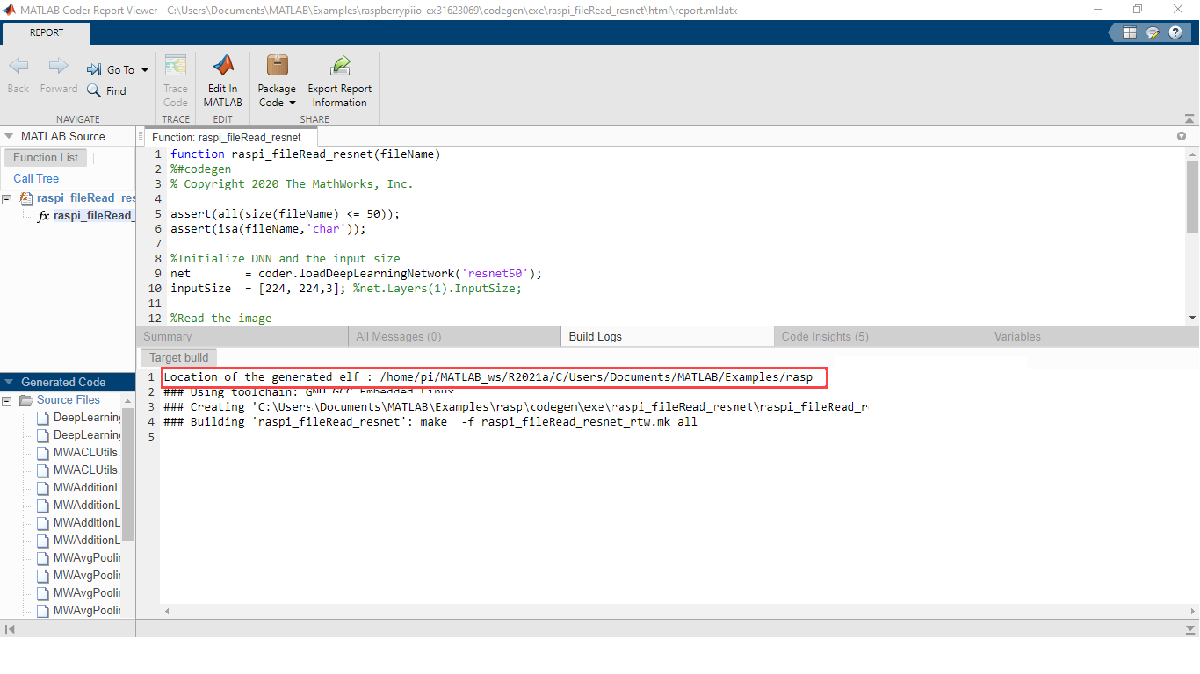

- Copy the image file to the hardware for prediction, using `putFile. `

            In this example,` coffeemug.png `is the image input to the executable and the location of the executable is same as the one you noted in the previous step.

            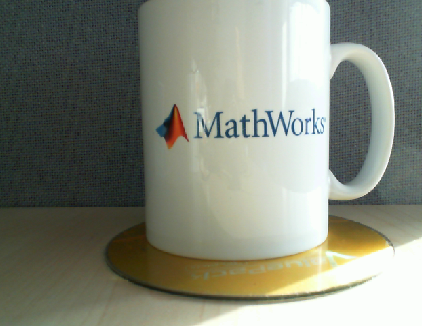

            4. You can provide the input image of your choice and copy it to the location of the generated elf using the following syntax:

            In this example,` coffeemug.png `is the image input to the executable and the location of the executable is `/home/pi/MATLAB_ws_R2021a/C/Users/Documents/MATLAB/Examples/rasp`.

## **Step 7: Run the Executable Program to Get Prediction Scores**

For MATLAB Desktop, use this command in the MATLAB Command Window to open an SSH terminal with Raspberry Pi, . 

For MATLAB Online, open an SSH terminal with Raspberry Pi. You can use Putty to connect to Hardware or directly use SSH commands in terminal for Unix.

In the terminal, log in by entering the user name and password for the Raspberry Pi.

Change the current directory to the directory where the executable was saved.

Run the executable on the Raspberry Pi by providing the `coffee.png` image as an input to the executable.

The executable starts classifying the object in the image file, then it predicts the object and displays its label and the probability associated with the object category.

## See Also

- [Identify Objects Within Live Video Using ResNet-50 on Raspberry Pi Hardware](docid:mlsupportpkg.example-resnet50_webcam)

- [Send Inputs to a MATLAB Function from Command Line of Raspberry Pi](docid:mlsupportpkg.example-simplesum_ssh)

*Copyright 2020 The MathWorks, Inc.*